# Cálculo de $\pi$

Monte Carlo methods, or Monte Carlo experiments, are a broad class of computational algorithms that rely on repeated **random sampling** to obtain numerical results.

[https://en.wikipedia.org/wiki/Monte_Carlo_method#Integration](https://en.wikipedia.org/wiki/Monte_Carlo_method#Integration)

## Area method

This method enables you to estimate areas (**definite integrals**) by generating a uniform sample of points and counting how many fall into a planar region.

If you generate a 2-D point (an ordered pair) uniformly at random within the unit square, then the probability that the point is inside the quarter circle is equal to the ratio of the area of the quarter circle divided by the area of the unit square. That is, P(point inside circle) = Area(quarter circle) / Area(unit square) = $\frac{\pi }{4}$

It is easy to use a Monte Carlo simulation to estimate the probability P:

- generate *n* random points uniformally distributed inside the unit square, and

- count the proportion that fall in the quarter circle

Genera 10000 puntos aleatorios

n = 10000;
x = rand(n, 1); % puntos x
y = rand(n, 1); % puntos y
r2 = x .^ 2 + y .^ 2 % eleva al cuadrado cada elemento

r2 =     0.6874
    1.7455
    0.7839
    1.0730
    0.5656
    0.0255
    0.9340
    0.2991
    0.9516
    1.0360


Encuentra los puntos que se encuentran dentro del área de interés (distancia al origen menor a 1) y fuera de ella

r = 1; % radio
dentro = r2 <= r ^ 2 % exito

dentro = 10000×1 logical array
   1
   0
   1
   0
   1
   1
   1
   1
   1
   0


fuera = r2 > r ^ 2 % fracaso

fuera = 10000×1 logical array
   0
   1
   0
   1
   0
   0
   0
   0
   0
   1


Grafica los puntos que caen adentro en azul y los que caen afuera en rojo

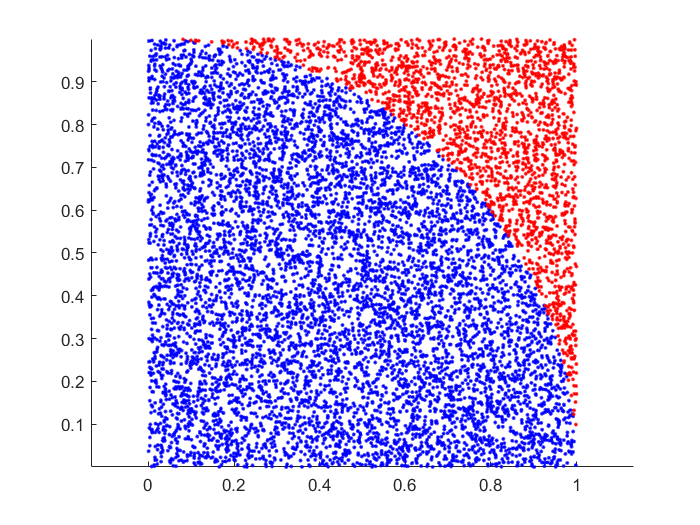

hold on
plot(x(dentro), y(dentro), 'b.')
plot(x(fuera), y(fuera), 'r.')
axis equal
hold off

Encuentra la proporción de puntos que están adentro (p) y de puntos que están afuera (q)

p = sum(dentro) / n

p = 0.7891

q = 1 - p

q = 0.2109

Encuentra la desviación estándar (proceso de Bernoulli)

sqrt(p * q)

ans = 0.4079

Calcula el intervalo de confianza (95%) para una proporción

porc = 0.95;
alfa = 1 - porc;
z = norminv(1 - alfa / 2);
error = z * sqrt(p * (1 - p) / n);
IC = [p  - error, p + error]

IC =     0.7811    0.7971


Repite el mismo experimento 100 veces, calcula la varianza, el error estándar y el intervalo de confianza.

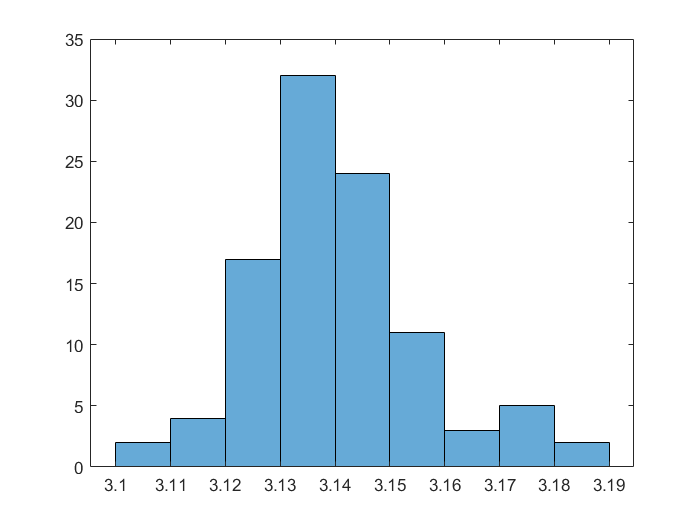

total = 100;
valores = zeros(1, total);

for i = 1:1:total    
    x = rand(1, n); % puntos x
    y = rand(1, n); % puntos y
    r2 = x .^ 2 + y .^ 2; % eleva al cuadrado cada elemento
    dentro = r2 <= r ^ 2; % exito
    valores(i) = 4 * sum(dentro) / n;
end

histogram(valores)

media = mean(valores);
var = var(valores);
desv = std(valores);
error = desv / sqrt(total);
fprintf('%7.4f +/- %6.4f\n', media, z * error)

 3.1404 +/- 0.0030


## Fórmula de Leibniz 

$\frac{\pi }{4}$=$1-\frac{1}{3}$$+\frac{1}{5}-\frac{1}{7}+\frac{1}{9}$-$\cdots$

Calcula el valor de $\pi$ usando la fórmula anterior. Detén el cálculo cuando la diferencia relativa entre el valor actual calculado y el anterior calculado sea menor a 0.0000001 o se hayan realizado 200 mil iteraciones.

n = 200000; % total de iteraciones
diff = 0.0000001; % error de truncamiento

anterior = 0;
actual = 1;
i = 1;

while (abs((actual - anterior) / actual)) > diff && i < n 
    anterior = actual;
    actual = anterior + ((-1) ^ i) / ((2 * i) + 1);
    i = i + 1;
end

actual = 4 * actual % valor de pi

actual = 3.1416